## Visualize Historical Portfolio VS Predicted Adverse Portfolio

Copyright (c) 2018, MathWorks, Inc.

This file is used to visaulize the default rates grouped by year on book for both historical portfolio and predicted portfolio

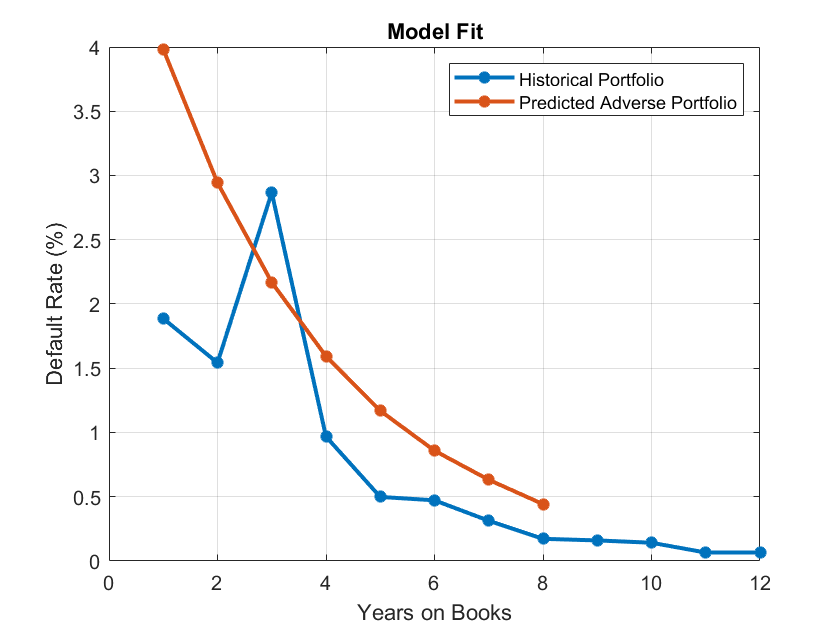

PredPD_historicalPortfolio = groupsummary(myLoanHistory,'YOB','mean','Default');
PredPD_AdversePortfolio = groupsummary(AdversePortfolio,'YOB','mean','PD');

figure;
plot(PredPD_historicalPortfolio.YOB,PredPD_historicalPortfolio.mean_Default*100,'-*','linewidth',2);
hold on
plot(PredPD_AdversePortfolio.YOB,PredPD_AdversePortfolio.mean_PD*100,'-*','linewidth',2);
hold off
xlabel('Years on Books')
ylabel('Default Rate (%)')
legend('Historical Portfolio', 'Predicted Adverse Portfolio')
title('Model Fit')
grid on